# 2D OBN data for diffraction imaging with FWI

## Introduction

See datailed description of the data in the paper:

On the rule of diffractions in velocity modelbuilding:  a full-waveform inversion example.

S. Dell, I. Abakumov, P. Znak, D. Gajewski, B. Kashtan, and A. Ponomarenko

**Author**: Abakumov Ivan

Freie Universität Berlin

**Publication date**: 24th July 2019

**E-mail**: [abakumov_ivan@mail.ru](mailto:abakumov_ivan@mail.ru)

## Add MLIB library

clear; close all; clc;
mlibfolder = '/home/ivan/Desktop/MLIB';
path(path, mlibfolder);
add_mlib_path;

## Basic sizes of model

The velocity model is described by G-array. It contains the following information: 

- Size of the velocity model: $G.nx, G.ny, G.nz$;

- Origine of the velocity model: $G.x0, G.y0, G.z0$; 

- Spatial increments of the velocity model: $G.dx, G.dy, G.dz$;

- $G.t0$ is a starting time for modeling, $G.dt$ is a time increment and  $G.nt$ is a number of time increments. 

G=GridClass;

%   [m]             [m]          [m]             [s]
G.x0 = -625;    G.y0 = 0;    G.z0 = -1250;   G.t0 = 0.00;            % initial point
G.nx =  501;    G.ny = 1;    G.nz =  401;    G.nt = 800;             % grid size
G.dx =  12.5;   G.dy = 12.5; G.dz =  12.5;   G.dt = 0.00275;           % grid step (meter)

G.gridInfo;

Information about grid:
x0=-625, dx=12.5, Nx=501.
y0=0, dy=12.5, Ny=1.
z0=-1250, dz=12.5, Nz=401.
t0=0, dt=0.00275, Nt=800.


G.setGrid;
Gold = oldGrid(G);

datafolder = [mlibfolder '/Examples/Paper_Role_of_diffractions_in_velocity_model_building/data'];

save([datafolder '/OBN_DIFF_G_file.mat'], 'G');

## Initial velocity model (baseline)

Initial velocity model consists of three layers: 

- Constant velocity water layer, $V_p = 1500 m/s$, depth $z=0.0-0.25 km$;

- Condtant gradient sedimentary layer, $V_p = 1500 + k \cdot (z-z_1)$, $z_1 = 0.25 km$, k = 1 s^{-1}$; 

- Constant velocity sedimentary layer, $V_p = 2750 m/s$. 

%     m   j
% -1250   1 +-----+-----------+-----------------------+-----------+-----+ 
%           |                                                           |
%           |      V = 1500 m/s                                         |
%           |     <------------------- sources ------------------>      |
%     0 101 +-----+-----------+-----------------------+-----------+-----+
%           |      V = 1500 m/s                                         |
%           |                 <--------- OBNs -------->                 |
%  +250 121 +-----+-----------+-----------------------+-----------+-----+
%           |                             ________                      |
%  +500 141 |                             | edge      V = V0 + k(z-z0)  |
%           |                             |           V0 = 1500 m/s     |
%  +750 161 |                                         z0 = 250  m       |
%           |                                         k  = 1    1/s     |
%           |   V = V + 500 m/s                                         |
%           |                                                           |
% +1500 221 |-----------------------------------------------------------|
%           |                                                           |
%           |                                                           |
%           |                                                           |
%           |                                         V = 2750 m/s      |
%           |                                                           |
%           |                                                           |
%           |                                                           |
%           |                                                           |
% +3750 401 +-----+-----------+-----------+-----------+-----------+-----+
%     m   -625    0          1250        2500        3750        5000  5625
%     i     1     51         151         251         351         451   501

bvelmod = zeros(G.nx, G.nz);

bvelmod(:, 1:121)=1500;
for i=122:221
    bvelmod(:, i)=bvelmod(:,i-1)+12.5;
end
for i=222:G.nz
    bvelmod(:,i)=bvelmod(:,221);
end

## True velocity model (monitor)

True velocity model includes edge diffractor

mvelmod = bvelmod;

% edge diffractor
for i=251:291
    jmin = 141; 
    jmax = 161-round((i-251)*0.5);
    for j=jmin:jmax
        mvelmod(i,j)=bvelmod(i,j)+500;
    end
end

save([datafolder '/OBN_DIFF_bvelmod.mat'], 'bvelmod');
save([datafolder '/OBN_DIFF_mvelmod.mat'], 'mvelmod');

## Save velocity as SEGY file

% Save traces as segy file 
seismic = s_data; 
seismic.traces = zeros(161, 401); 
seismic.headers = zeros(2,  401); 

% change header_info
seismic.header_info(1,:) = cellstr(['cdp        '; 'no         '; 'source no  ']);
seismic.header_info(2,:) = cellstr(['cdp_x      '; 'no         '; 'receiver no']);

% change traces and headers
for i=51:451
    seismic.traces(:,  i-50) = mvelmod(i,101:261);
    seismic.headers(1, i-50) = 2*G.xx(i)/G.dx;
    seismic.headers(2, i-50) = G.xx(i);
end

% change time information
seismic.first = G.zz(101); 
seismic.last  = G.zz(261); 
seismic.step  = G.dz*1000; 

% change data information 
seismic.name = cellstr('monitor velocity');
seismic.history(1) = cellstr(date);
seismic.history(2) = cellstr('Abakumov Ivan');
seismic.history(3) = cellstr('monitor velocity');


write_segy_file(seismic, [datafolder '/OBN_DIFF_mvelmod.sgy']);

EBCDIC reel header written


Binary reel header written
Header "ds_seqno" not found in dataset and assumed to be zero
Header "ffid" not found in dataset and assumed to be zero
Header "o_trace_no" not found in dataset and assumed to be zero
Header "source" not found in dataset and assumed to be zero
Header "seq_cdp" not found in dataset and assumed to be zero
Header "trc_type" not found in dataset and assumed to be zero
Header "offset" not found in dataset and assumed to be zero
Header "depth" not found in dataset and assumed to be zero
Header "sou_h2od" not found in dataset and assumed to be zero
Header "rec_h2od" not found in dataset and assumed to be zero
Header "sou_x" not found in dataset and assumed to be zero
Header "sou_y" not found in dataset and assumed to be zero
Header "sou_elev" not found in dataset and assumed to be zero
Header "rec_x" not found in dataset and assumed to be zero
Header "rec_y" not found in dataset and assumed to be zero
Header "rec_elev" not found in dataset and assumed to be zero
Hea

## Acquisition geomerty

Acquisition geometry includes the line of shots on the top of the water layer and the line of receivers on the water bottom. In FWI shots and receivers are replaced, however the wavefields coinside due to the resiprocity principle. 

% Note: sources and receivers are changed!

acq.gsx = 151:8:351;
acq.gsz = 121*ones(size(acq.gsx));
acq.grx = 51:1:451;
acq.grz = 101*ones(size(acq.grx));
acq.sx = (acq.gsx-1)*G.dx + G.x0;
acq.sz = (acq.gsz-1)*G.dz + G.z0;
acq.rx = (acq.grx-1)*G.dx + G.x0;
acq.rz = (acq.grz-1)*G.dz + G.z0;

save([datafolder '/OBN_DIFF_acquisition.mat'], 'acq');

## Visualize initial and true velocity models

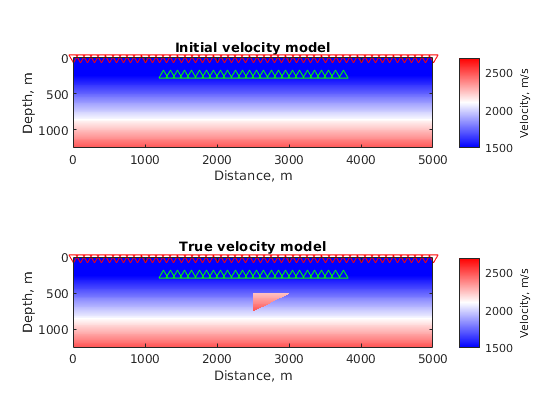

figure(1)
subplot(2,1,1)
imagesc(G.xx, G.zz, bvelmod')
hold on
plot(acq.sx, acq.sz, 'g^')
plot(acq.rx(1:8:401), acq.rz(1:8:401), 'rv')
axis('equal')
set(gca, 'YDir', 'Reverse')
axis([0 5000 0 1250]); 
c = colorbar('Ticks', [1500,2000,2500]);
c.Label.String = 'Velocity, m/s';
caxis([1500, 2700])
title('Initial velocity model')
xlabel('Distance, m')
ylabel('Depth, m')

subplot(2,1,2)
imagesc(G.xx, G.zz, mvelmod')
hold on
plot(acq.sx, acq.sz, 'g^')
plot(acq.rx(1:8:401), acq.rz(1:8:401), 'rv')
axis('equal')
set(gca, 'YDir', 'Reverse')
axis([0 5000 0 1250]); 
c = colorbar('Ticks', [1500,2000,2500]);
c.Label.String = 'Velocity, m/s';
caxis([1500, 2700])
title('True velocity model')
xlabel('Distance, m')
ylabel('Depth, m')
colormap(makeColorMap([0 0 1],[1 1 1],[1 0 0],100));

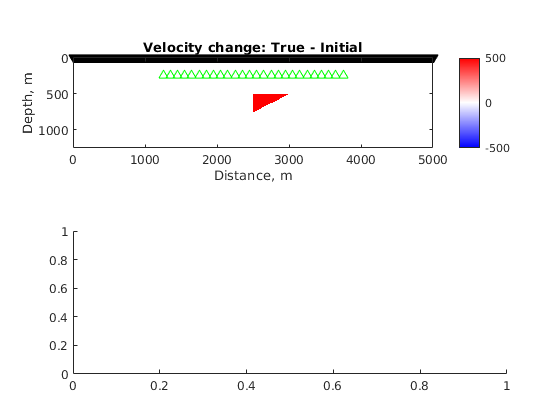



figure(2)
subplot(2,1,1)
imagesc(G.xx, G.zz, mvelmod'-bvelmod')
hold on
plot(acq.sx, acq.sz, 'g^')
plot(acq.rx, acq.rz, 'blackv')
axis('equal')
set(gca, 'YDir', 'Reverse')
axis([0 5000 0 1250]); 
caxis([-500, 500])
colorbar
title('Velocity change: True - Initial')
xlabel('Distance, m')
ylabel('Depth, m')
colormap(makeColorMap([0 0 1],[1 1 1],[1 0 0],100));

subplot(2,1,2)

stanum = 26;  
S = [acq.sx(stanum), acq.sz(stanum)];
tti = FSM2D(Gold,S,bvelmod);
sta(:,1) = acq.rx(1:10:end); 
sta(:,2) = acq.rz(1:10:end); 
ray_visualization2D(tti, bvelmod, Gold, sta)

Dot indexing is not supported for variables of this type.

Error in ray_visualization2D (line 6)
x = zeros(2,G.nx);

hold on
plot(acq.sx, acq.sz, 'g^')
plot(acq.rx, acq.rz, 'blackv')
axis('equal')
set(gca, 'YDir', 'Reverse')
axis([0 5000 0 1250]); 
caxis([1500, 2700])
colorbar
title('True velocity model')
xlabel('Distance, m')
ylabel('Depth, m')

figure(3)
imagesc(G.xx, G.zz, mvelmod')
hold on
plot(acq.sx, acq.sz, 'g^')
plot(acq.rx, acq.rz, 'blackv')
axis('equal')
set(gca, 'YDir', 'Reverse')
axis([G.xx(1) G.xx(end) G.zz(1) G.zz(end)]);
caxis([1500, 2700])
colorbar
title('Velocity model for FWI')
xlabel('Distance, m')
ylabel('Depth, m')
colormap(makeColorMap([0 0 1],[1 1 1],[1 0 0],100));

## Plot figures for paper

fig = figure('Position', [900 400 550 300])

fig =   Figure (3) with properties:

      Number: 3
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [900 400 550 300]
       Units: 'pixels'

  Show all properties


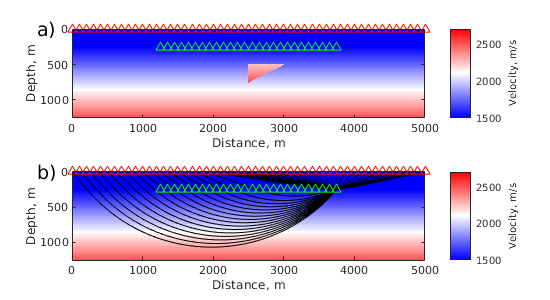

subplot(2,1,1)
imagesc(G.xx, G.zz, mvelmod')
hold on
plot(acq.sx, acq.sz, 'g^')
plot(acq.rx(1:8:401), acq.rz(1:8:401), 'r^')
axis('equal')
set(gca, 'YDir', 'Reverse')
axis([0 5000 0 1250]); 
c = colorbar('Ticks', [1500,2000,2500]);
c.Label.String = 'Velocity, m/s';
caxis([1500, 2700])
%title('True velocity model')
xlabel('Distance, m')
ylabel('Depth, m')
colormap(makeColorMap([0 0 1],[1 1 1],[1 0 0],100));
text(-500,0,'a)','FontSize',14);

subplot(2,1,2)
stanum = 26;  
S = [acq.sx(stanum), acq.sz(stanum)];
tti = FSM2D(Gold,S,bvelmod);
sta(:,1) = acq.rx(1:10:end); 
sta(:,2) = acq.rz(1:10:end); 
ray_visualization2D(tti, bvelmod, G, sta, 'black')
hold on
plot(acq.sx, acq.sz, 'g^')
plot(acq.rx(1:8:401), acq.rz(1:8:401), 'r^')
axis('equal')
set(gca, 'YDir', 'Reverse')
axis([0 5000 0 1250]); 
caxis([1500, 2700])
c = colorbar('Ticks', [1500,2000,2500]);
c.Label.String = 'Velocity, m/s';
title('')
xlabel('Distance, m')
ylabel('Depth, m')
text(-500,0,'b)','FontSize',14);

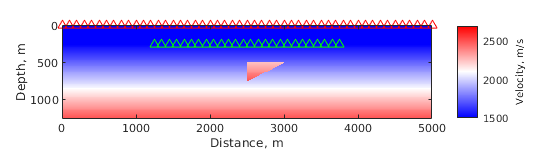


figure(23)
fig = figure('Position', [100 100 550 150]);
imagesc(G.xx, G.zz, mvelmod')
hold on
plot(acq.sx, acq.sz, 'g^')
plot(acq.rx(1:8:401), acq.rz(1:8:401), 'r^')
axis('equal')
set(gca, 'YDir', 'Reverse')
axis([0 5000 0 1250]); 
c = colorbar('Ticks', [1500,2000,2500]);
c.Label.String = 'Velocity, m/s';
caxis([1500, 2700])
%title('True velocity model')
xlabel('Distance, m')
ylabel('Depth, m')
colormap(makeColorMap([0 0 1],[1 1 1],[1 0 0],100));

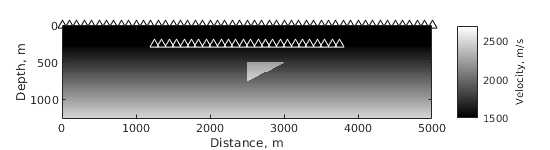

%text(-500,0,'a)','FontSize',14);

figure(24)
fig = figure('Position', [100 100 550 150]);
imagesc(G.xx, G.zz, mvelmod')
hold on
plot(acq.sx, acq.sz, 'w^')
plot(acq.rx(1:8:401), acq.rz(1:8:401), 'k^')
axis('equal')
set(gca, 'YDir', 'Reverse')
axis([0 5000 0 1250]); 
c = colorbar('Ticks', [1500,2000,2500]);
c.Label.String = 'Velocity, m/s';
caxis([1500, 2700])
%title('True velocity model')
xlabel('Distance, m')
ylabel('Depth, m')
colormap('gray')

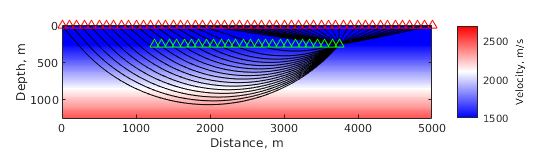

%colormap(makeColorMap([0 0 1],[1 1 1],[1 0 0],100));
%text(-500,0,'a)','FontSize',14);

figure(25)
fig = figure('Position', [100 100 550 150]);
stanum = 26;  
S = [acq.sx(stanum), acq.sz(stanum)];
tti = FSM2D(Gold,S,bvelmod);
sta(:,1) = acq.rx(1:10:end); 
sta(:,2) = acq.rz(1:10:end); 
ray_visualization2D(tti, bvelmod, G, sta, 'black')
hold on
plot(acq.sx, acq.sz, 'g^')
plot(acq.rx(1:8:401), acq.rz(1:8:401), 'r^')
axis('equal')
set(gca, 'YDir', 'Reverse')
axis([0 5000 0 1250]); 
caxis([1500, 2700])
c = colorbar('Ticks', [1500,2000,2500]);
colormap(makeColorMap([0 0 1],[1 1 1],[1 0 0],100));
c.Label.String = 'Velocity, m/s';
title('')
xlabel('Distance, m')
ylabel('Depth, m')

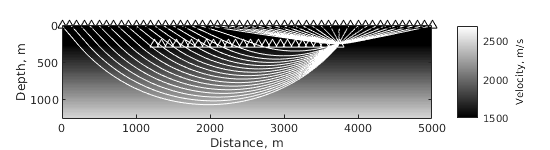

%text(-500,0,'b)','FontSize',14);

figure(26)
fig = figure('Position', [100 100 550 150]);
stanum = 26;  
S = [acq.sx(stanum), acq.sz(stanum)];
tti = FSM2D(Gold,S,bvelmod);
sta(:,1) = acq.rx(1:10:end); 
sta(:,2) = acq.rz(1:10:end); 
ray_visualization2D(tti, bvelmod, G, sta, 'w')
hold on
plot(acq.sx, acq.sz, 'w^')
plot(acq.rx(1:8:401), acq.rz(1:8:401), 'k^')
axis('equal')
set(gca, 'YDir', 'Reverse')
axis([0 5000 0 1250]); 
caxis([1500, 2700])
c = colorbar('Ticks', [1500,2000,2500]);
colormap('gray');
c.Label.String = 'Velocity, m/s';
title('')
xlabel('Distance, m')
ylabel('Depth, m')

%text(-500,0,'b)','FontSize',14);

## Calculate traveltimes of direct waves

tshift = 0.0825; 

tdir = zeros(length(acq.sx), length(acq.rx)); 

for s=1:length(acq.sx)
    S = [acq.sx(s), acq.sz(s)];
    tti = FSM2D(Gold,S,bvelmod);
    
    for r=1:length(acq.rx)
        tdir(s,r) = tti(acq.grx(r),acq.grz(r));
    end
end

## Calculate traveltimes of diffraction events

S1 = [2500, 500];
S2 = [2500, 750];
S3 = [3000, 500];

tti1 = FSM2D(Gold,S1,mvelmod);
tti2 = FSM2D(Gold,S2,mvelmod);
tti3 = FSM2D(Gold,S3,mvelmod);

tdif1 = zeros(length(acq.sx), length(acq.rx)); 
tdif2 = zeros(length(acq.sx), length(acq.rx)); 
tdif3 = zeros(length(acq.sx), length(acq.rx)); 

for s=1:length(acq.sx)
    for r=1:length(acq.rx)
        tdif1(s,r) = tti1(acq.gsx(s),acq.gsz(s)) + tti1(acq.grx(r),acq.grz(r));
        tdif2(s,r) = tti2(acq.gsx(s),acq.gsz(s)) + tti2(acq.grx(r),acq.grz(r));
        tdif3(s,r) = tti3(acq.gsx(s),acq.gsz(s)) + tti3(acq.grx(r),acq.grz(r));
    end
end

## Make monitor data

required = 0; 
if(required)
    % Frequency (for FWI)
    % 12.5 m 
    %fpeak = 8; 
    %fpeak = 20; 
    fpeak = 20; 

    % Number of threads
    nthreads = 3; 

    traces = zeros(length(acq.rx), length(acq.sx), G.nt);

    for ishot=1:nthreads:length(acq.sx)
        shotnum = ishot:min(length(acq.sx), ishot+nthreads-1); 
        [f10,~,~] = Get_FD_forward(G, acq, shotnum, fpeak, mvelmod);
        for s=1:length(shotnum) 
            for r=1:length(acq.rx)
                traces(r,shotnum(s),:) = f10(acq.grx(r),acq.grz(r),:,s);
            end
        end
    end

    % Save traces as segy file 
    seismic = s_data; 
    seismic.traces = zeros(G.nt, length(acq.rx)*length(acq.sx)); 
    seismic.headers = zeros(8,    length(acq.rx)*length(acq.sx)); 

    % change header_info
    seismic.header_info(1,:) = cellstr(['ffid       '; 'no         '; 'source no  ']);
    seismic.header_info(2,:) = cellstr(['o_trace_no '; 'no         '; 'receiver no']);
    seismic.header_info(3,:) = cellstr(['sou_x      '; 'm          '; 'sx         ']);
    seismic.header_info(4,:) = cellstr(['sou_elev   '; 'm          '; 'sz         ']);
    seismic.header_info(5,:) = cellstr(['rec_x      '; 'm          '; 'rx         ']);
    seismic.header_info(6,:) = cellstr(['rec_elev   '; 'm          '; 'rz         ']);
    seismic.header_info(7,:) = cellstr(['cdp        '; 'no         '; 'cdp        ']);
    seismic.header_info(8,:) = cellstr(['offset     '; 'm          '; 'offset     ']);

    % change traces and headers
    for s=1:length(acq.sx)
        for r=1:length(acq.rx)
            seismic.traces(:,  r + (s-1)*length(acq.rx)) = traces(r,s,:);
            seismic.headers(1, r + (s-1)*length(acq.rx)) = s;
            seismic.headers(2, r + (s-1)*length(acq.rx)) = r;
            seismic.headers(3, r + (s-1)*length(acq.rx)) = acq.sx(s);
            seismic.headers(4, r + (s-1)*length(acq.rx)) = acq.sz(s);
            seismic.headers(5, r + (s-1)*length(acq.rx)) = acq.rx(r);
            seismic.headers(6, r + (s-1)*length(acq.rx)) = acq.rz(r);
            seismic.headers(7, r + (s-1)*length(acq.rx)) = (acq.sx(s)+acq.rx(r))/G.dx;
            seismic.headers(8, r + (s-1)*length(acq.rx)) = (acq.sx(s)-acq.rx(r))/2;
        end
    end

    % change time information
    seismic.first = G.t0; 
    seismic.last = G.mt; 
    seismic.step = G.dt*1000; 

    % change data information 
    seismic.name = cellstr('OBN data, diffraction');
    seismic.history(1) = cellstr(date);
    seismic.history(2) = cellstr('Abakumov Ivan');
    seismic.history(3) = cellstr('OBN data, baseline');
    seismic.history(4) = cellstr([num2str(fpeak) ' Hz']);

    write_segy_file(seismic, [datafolder '/OBN_DIFF_monitor_20Hz.sgy']);

    % convert to SU
    % segyread tape=OBN_DIFF_monitor_20Hz.sgy > OBN_DIFF_monitor_20Hz.su 

end

## Make snapshots and monitor data

fpeak = 20; 

for ishot=1:1
    shotnum = [8 16 24]; 
 
    % monitor 
    [f10,~,~] = Get_FD_forward(G, acq, shotnum, fpeak, mvelmod);
    s10 = zeros(length(acq.rx), G.nt,length(shotnum));
    for s=1:length(shotnum) 
        for i=1:length(acq.rx)
            s10(i,:,s) = f10(acq.grx(i),acq.grz(i),:,s);
        end
    end
    
    % baseline 
    [f09,~,~] = Get_FD_forward(G, acq, shotnum, fpeak, bvelmod);
    s09 = zeros(length(acq.rx), G.nt,length(shotnum));
    for s=1:length(shotnum) 
        for i=1:length(acq.rx)
            s09(i,:,s) = f09(acq.grx(i),acq.grz(i),:,s);
        end
    end
end

Constant dencity acoustic modeling: rho=const, vs=0.
el2d will be executed with 8 threads.
Minimum number of grid points per shortest wavelength: 3 >= 2.
Stability parameter: 1.28876 > 1.
Computing wavefields...Dimensions for output arrays: 501 x 401 x 800 x 3


Stability parameter: 1.28875 > 1.
Parameters:
nout = 3;
nx = 501; nz = 401;
nxl = 501; nzl = 401;
nsht = 3; nb = 0; ngob=30;
nt = 800; dt = 0.002750; fpeak = 20.000000;
dx = 12.500000; dz = 12.500000;
bc = 0, stype = 0; wtype = 0; atype=1;
sxi[0] = 206; szi[0] = 120;
lxi[0] = 0; lzi[0] = 0;
Calling master routine from gateway routine...
Master routine terminated successfully.
Done. Elapsed time is 59.882978 seconds.


Constant dencity acoustic modeling: rho=const, vs=0.
el2d will be executed with 8 threads.
Minimum number of grid points per shortest wavelength: 3 >= 2.
Stability parameter: 1.28876 > 1.
Computing wavefields...Dimensions for output arrays: 501 x 401 x 800 x 3


Stability parameter: 1.28875 > 1.
Parameters:
nout = 3;
nx = 501; nz = 401;
nxl = 501; nzl = 401;
nsht = 3; nb = 0; ngob=30;
nt = 800; dt = 0.002750; fpeak = 20.000000;
dx = 12.500000; dz = 12.500000;
bc = 0, stype = 0; wtype = 0; atype=1;
sxi[0] = 206; szi[0] = 120;
lxi[0] = 0; lzi[0] = 0;
Calling master routine from gateway routine...
Master routine terminated successfully.
Done. Elapsed time is 60.192456 seconds.


## Plot snapshots

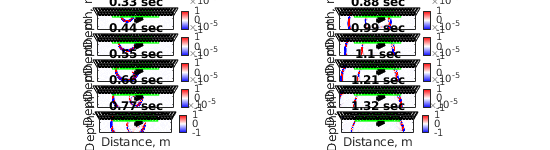

i=1;

figure(4)
TIM = [121 321 161 361 201 401 241 441 281 481]; 
for j=1:10
    subplot(5,2,j)
    tim = TIM(j);
    imagesc(G.xx, G.zz, squeeze(f10(:,:,tim,i))')
    hold on
    plot(acq.sx, acq.sz, 'g^')
    plot(acq.rx(1:8:401), acq.rz(1:8:401), 'kv')
    plot(linspace(2500,3000,250), linspace(750,500,250), '-black', 'LineWidth',2); 
    plot(linspace(2500,3000,250), linspace(500,500,250), '-black', 'LineWidth',2);
    plot(linspace(2500,2500,250), linspace(500,750,250), '-black', 'LineWidth',2);
    axis('equal')
    set(gca,'XTickLabel',[]);
    set(gca,'YTickLabel',[]);
    set(gca, 'YDir', 'Reverse')
    xlabel('Distance, m'); 
    ylabel('Depth, m');
    %axis([1250 3750 250 1000]); 
    axis([0 5000 0 1250]); 
    caxis([-0.00001, 0.00001])
    title([num2str(G.tt(tim)) ' sec'])
    colormap(makeColorMap([0 0 1],[1 1 1],[1 0 0],100));
    colorbar
end

## Plot CR gathers

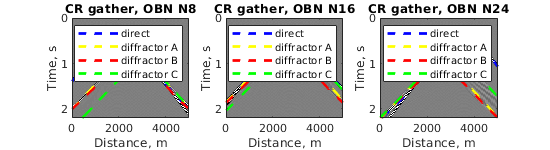

figure(5)
for i=1:3
    subplot(1,3,i)
    imagesc(acq.rx, G.tt, squeeze(s10(:,:,i))')
    caxis([-0.00001, 0.00001])
    %colormap(makeColorMap([0 0 1],[1 1 1],[1 0 0],100));
    colormap('gray')
    hold on
    ylabel('Time, s');
    xlabel('Distance, m');
    title(['CR gather, OBN N' num2str(shotnum(i))]); 
    plot(acq.rx, tdir(shotnum(i),:)+tshift,  '--b', 'LineWidth',2);
    plot(acq.rx, tdif1(shotnum(i),:)+tshift, '--y', 'LineWidth',2);
    plot(acq.rx, tdif2(shotnum(i),:)+tshift, '--r', 'LineWidth',2);
    plot(acq.rx, tdif3(shotnum(i),:)+tshift, '--g', 'LineWidth',2);
    %legend('direct', 'diffractor (2500, 500)', 'diffractor (2500, 750)', 'diffractor (3000, 500)' )
    legend('direct', 'diffractor A', 'diffractor B', 'diffractor C' )
    
end

## Plot CR gathers - only diffractions

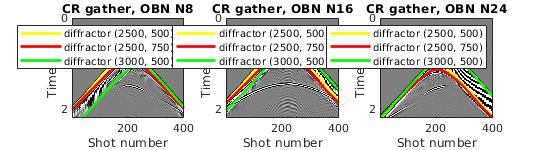

figure(6)
for i=1:3
    subplot(1,3,i)
    imagesc(1:401, G.tt, squeeze(s10(:,:,i)-s09(:,:,i))')
    caxis([-0.0000001, 0.0000001])
    %colormap(makeColorMap([0 0 1],[1 1 1],[1 0 0],100));
    colormap('gray')
    hold on
    ylabel('Time, sec');
    xlabel('Shot number');
    title(['CR gather, OBN N' num2str(shotnum(i))]); 
    %plot(1:401, tdir(shotnum(i),:)+tshift, '-black', 'LineWidth',4);
    plot(1:401, tdif1(shotnum(i),:)+tshift, '-y', 'LineWidth',2);
    plot(1:401, tdif2(shotnum(i),:)+tshift, '-r', 'LineWidth',2);
    plot(1:401, tdif3(shotnum(i),:)+tshift, '-g', 'LineWidth',2);
    %legend('direct', 'diffractor (2500, 500)', 'diffractor (2500, 750)', 'diffractor (3000, 500)' )
    legend('diffractor (2500, 500)', 'diffractor (2500, 750)', 'diffractor (3000, 500)' )
end

## Plot for paper abstract

i=1

i = 1

fig = figure('Position', [900 400 550 500])

fig =   Figure (8) with properties:

      Number: 8
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [900 400 550 500]
       Units: 'pixels'

  Show all properties


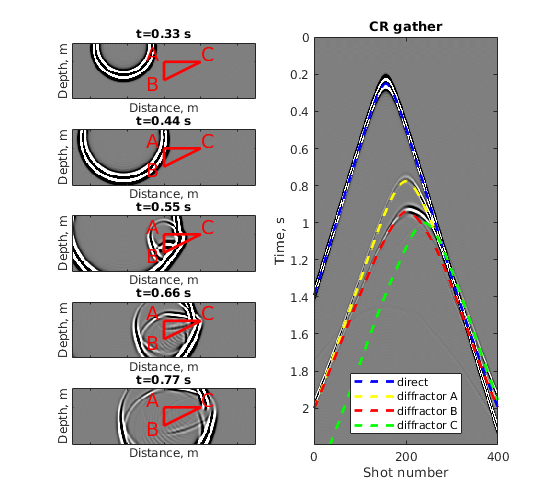

%TIM = [161 321 201 361 241 401 281 281 281 481]; % i = 1
TIM = [121 321 161 361 201 401 241 441 281 481]; % i = 1
%TIM = [41 321 81 361 121 401 161 441 201 481]; % i = 2
%TIM = [161 321 201 361 241 401 281 441 321 481]; % i = 3

for j=[1 3 5 7,9]
    subplot(5,2,j)
    tim = TIM(j);
    imagesc(G.xx, G.zz, squeeze(f10(:,:,tim,i))')
    hold on
    %plot(acq.sx, acq.sz, 'g^')
    %plot(acq.rx(1:8:401), acq.rz(1:8:401), 'rv')
    plot(linspace(2500,3000,250), linspace(750,500,250), '-r', 'LineWidth',2); 
    plot(linspace(2500,3000,250), linspace(500,500,250), '-r', 'LineWidth',2);
    plot(linspace(2500,2500,250), linspace(500,750,250), '-r', 'LineWidth',2);
    axis('equal')
    set(gca,'XTickLabel',[]);
    set(gca,'YTickLabel',[]);
    set(gca, 'YDir', 'Reverse')
    xlabel('Distance, m'); 
    ylabel('Depth, m');
    axis([1250 3750 250 1000]); 
    %axis([0 5000 0 1250]); 
    caxis([-0.00001, 0.00001])
    title(['t=' num2str(G.tt(tim)) ' s'])
    colormap(makeColorMap([0 0 1],[1 1 1],[1 0 0],100));
    %colorbar
    text(2250,400,'A','FontSize',14, 'Color', 'red');
    text(2250,800,'B','FontSize',14, 'Color', 'red');
    text(3000,400,'C','FontSize',14, 'Color', 'red');
end

subplot(5,2,[2,4,6,8,10])
imagesc(acq.rx/G.dx, G.tt, squeeze(s10(:,:,i))')
caxis([-0.00001, 0.00001])
%colormap(makeColorMap([0 0 1],[1 1 1],[1 0 0],100));
colormap('gray')
hold on
ylabel('Time, s');
xlabel('Shot number');
title('CR gather'); 
plot(acq.rx/G.dx, tdir(shotnum(i),:)+tshift,  '--b', 'LineWidth',2);
plot(acq.rx/G.dx, tdif1(shotnum(i),:)+tshift, '--y', 'LineWidth',2);
plot(acq.rx/G.dx, tdif2(shotnum(i),:)+tshift, '--r', 'LineWidth',2);
plot(acq.rx/G.dx, tdif3(shotnum(i),:)+tshift, '--g', 'LineWidth',2);
%legend('direct', 'diffractor (2500, 500)', 'diffractor (2500, 750)', 'diffractor (3000, 500)' )
legend('direct', 'diffractor A', 'diffractor B', 'diffractor C', 'Location', 'south' )

i=1

i = 1

figure(34)
fig = figure('Position', [900 400 550 500])

fig =   Figure (12) with properties:

      Number: 12
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [900 400 550 500]
       Units: 'pixels'

  Show all properties


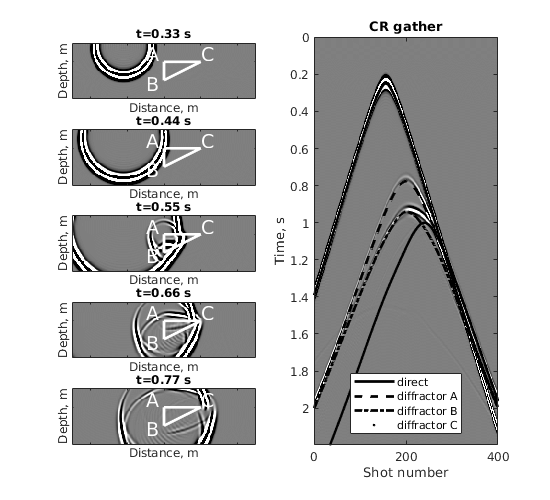

%TIM = [161 321 201 361 241 401 281 281 281 481]; % i = 1
TIM = [121 321 161 361 201 401 241 441 281 481]; % i = 1
%TIM = [41 321 81 361 121 401 161 441 201 481]; % i = 2
%TIM = [161 321 201 361 241 401 281 441 321 481]; % i = 3

for j=[1 3 5 7,9]
    subplot(5,2,j)
    tim = TIM(j);
    imagesc(G.xx, G.zz, squeeze(f10(:,:,tim,i))')
    hold on
    %plot(acq.sx, acq.sz, 'g^')
    %plot(acq.rx(1:8:401), acq.rz(1:8:401), 'rv')
    plot(linspace(2500,3000,250), linspace(750,500,250), '-w', 'LineWidth',2); 
    plot(linspace(2500,3000,250), linspace(500,500,250), '-W', 'LineWidth',2);
    plot(linspace(2500,2500,250), linspace(500,750,250), '-W', 'LineWidth',2);
    axis('equal')
    set(gca,'XTickLabel',[]);
    set(gca,'YTickLabel',[]);
    set(gca, 'YDir', 'Reverse')
    xlabel('Distance, m'); 
    ylabel('Depth, m');
    axis([1250 3750 250 1000]); 
    %axis([0 5000 0 1250]); 
    caxis([-0.00001, 0.00001])
    title(['t=' num2str(G.tt(tim)) ' s'])
    colormap(makeColorMap([0 0 1],[1 1 1],[1 0 0],100));
    %colorbar
    text(2250,400,'A','FontSize',14, 'Color', 'w');
    text(2250,800,'B','FontSize',14, 'Color', 'w');
    text(3000,400,'C','FontSize',14, 'Color', 'w');
end

subplot(5,2,[2,4,6,8,10])
imagesc(acq.rx/G.dx, G.tt, squeeze(s10(:,:,i))')
caxis([-0.00001, 0.00001])
%colormap(makeColorMap([0 0 1],[1 1 1],[1 0 0],100));
colormap('gray')
hold on
ylabel('Time, s');
xlabel('Shot number');
title('CR gather'); 
plot(acq.rx/G.dx, tdir(shotnum(i),:)+tshift,  '-k', 'LineWidth',2);
plot(acq.rx/G.dx, tdif1(shotnum(i),:)+tshift, '--k', 'LineWidth',2);
plot(acq.rx/G.dx, tdif2(shotnum(i),:)+tshift, '-.k', 'LineWidth',2);
plot(acq.rx/G.dx, tdif3(shotnum(i),:)+tshift, '.k', 'LineWidth',2);
%legend('direct', 'diffractor (2500, 500)', 'diffractor (2500, 750)', 'diffractor (3000, 500)' )
legend('direct', 'diffractor A', 'diffractor B', 'diffractor C', 'Location', 'south' )

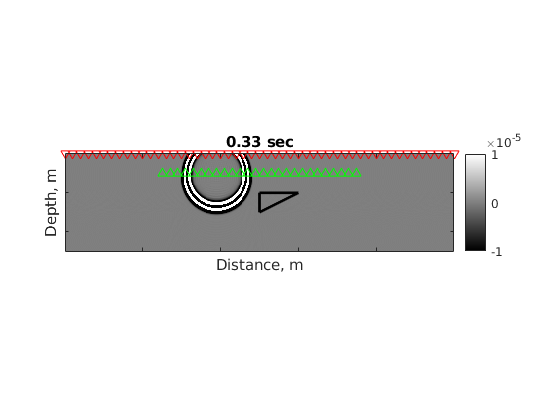

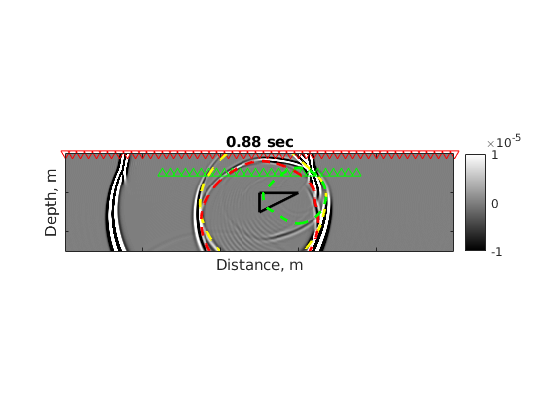

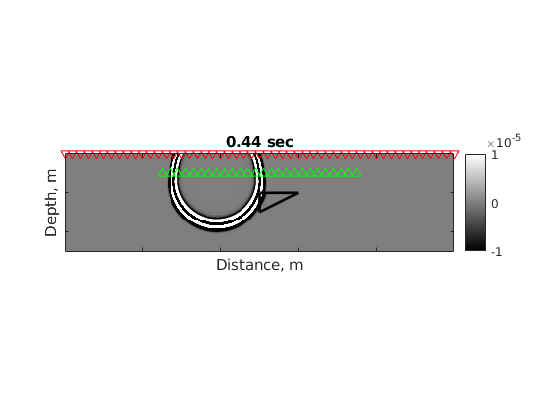

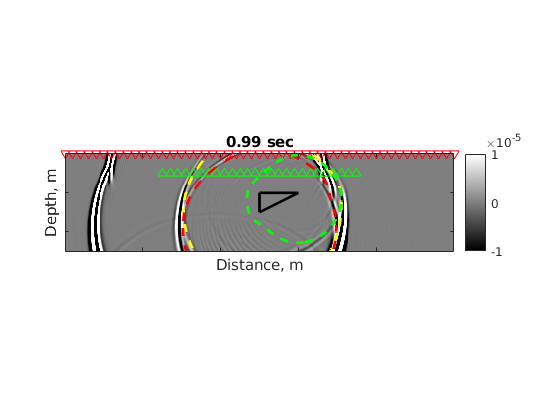

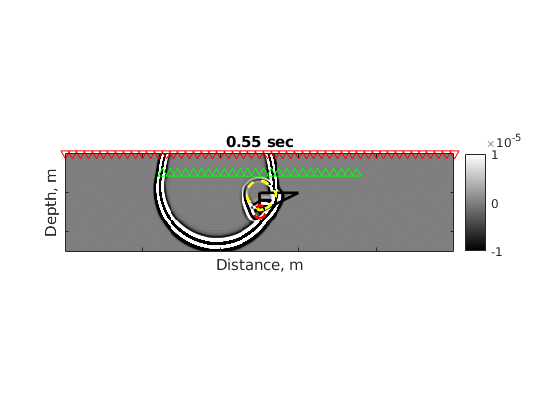

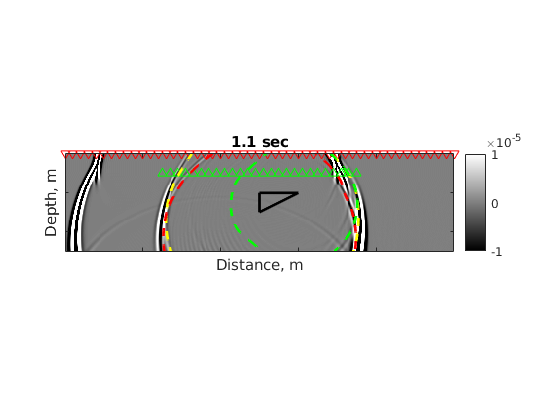

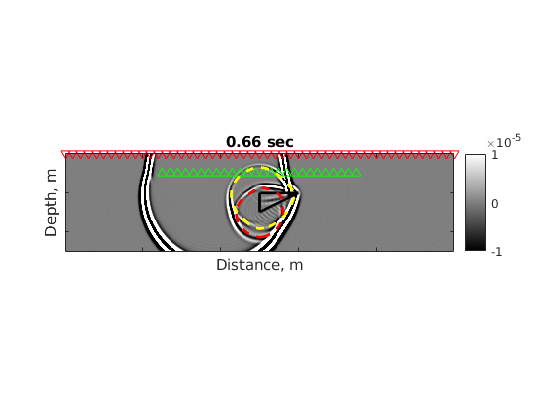

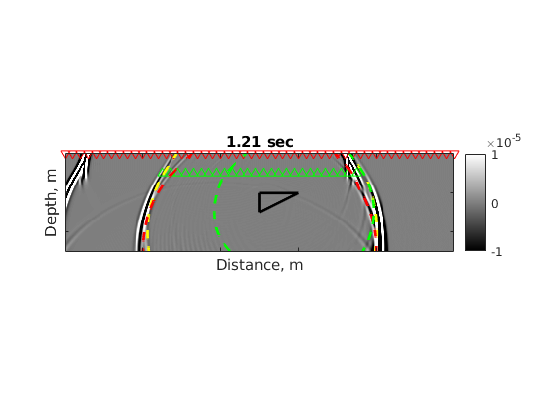

for j=1:1:9
    jj = 30+j; 
    figure(jj)
    tim = TIM(j);
    imagesc(G.xx, G.zz, squeeze(f10(:,:,tim,i))')
    hold on
    plot(acq.sx, acq.sz, 'g^')
    plot(acq.rx(1:8:401), acq.rz(1:8:401), 'rv')
    plot(linspace(2500,3000,250), linspace(750,500,250), '-black', 'LineWidth',2); 
    plot(linspace(2500,3000,250), linspace(500,500,250), '-black', 'LineWidth',2);
    plot(linspace(2500,2500,250), linspace(500,750,250), '-black', 'LineWidth',2);
    axis('equal')
    set(gca,'XTickLabel',[]);
    set(gca,'YTickLabel',[]);
    set(gca, 'YDir', 'Reverse')
    [~,h] = contour(G.xx,fliplr(G.zz),flipud(tti1(acq.gsx(8),acq.gsz(8))+tti1'+tshift),[G.tt(tim) G.tt(tim)], 'color','y','ShowText','off');
    h.LineWidth = 2;
    h.LineStyle = '--'; 
    [~,h] = contour(G.xx,fliplr(G.zz),flipud(tti2(acq.gsx(8),acq.gsz(8))+tti2'+tshift),[G.tt(tim) G.tt(tim)], 'color','r','ShowText','off');
    h.LineWidth = 2;
     h.LineStyle = '--'; 
    [C,h] = contour(G.xx,fliplr(G.zz),flipud(tti3(acq.gsx(8),acq.gsz(8))+tti3'+tshift),[G.tt(tim) G.tt(tim)], 'color','g','ShowText','off');
    h.LineWidth = 2;
     h.LineStyle = '--'; 
    xlabel('Distance, m'); 
    ylabel('Depth, m');
    %axis([1250 3750 250 1000]); 
    axis([0 5000 0 1250]); 
    caxis([-0.00001, 0.00001])
    title([num2str(G.tt(tim)) ' sec'])
    colormap(makeColorMap([0 0 1],[1 1 1],[1 0 0],100));
    colormap('gray')
    colorbar
    
end